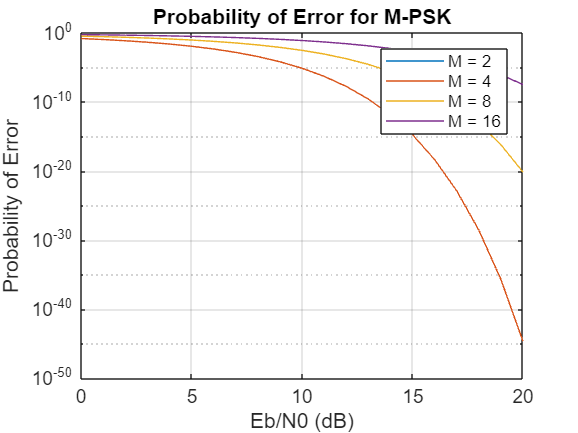

% MATLAB code for plotting probability of error for different values of M in M-PSK

% Define the values of M
M_values = [2, 4, 8, 16];

% Define the range of Eb/N0 (in dB)
EbN0_dB = 0:1:20;

% Convert Eb/N0 from dB to linear scale
EbN0 = 10.^(EbN0_dB/10);

% Preallocate the probability of error array
Pe = zeros(length(M_values), length(EbN0));

% Calculate the probability of error for each M
for i = 1:length(M_values)
    M = M_values(i);
    k = log2(M); % Number of bits per symbol
    Pe(i, :) = 2*qfunc(sqrt(2*EbN0*k)*sin(pi/M));
end

% Plot the results
figure;
for i = 1:length(M_values)
    semilogy(EbN0_dB, Pe(i, :), 'DisplayName', sprintf('M = %d', M_values(i)));
    hold on;
end

grid on;
xlabel('Eb/N0 (dB)');
ylabel('Probability of Error');
title('Probability of Error for M-PSK');
legend show;

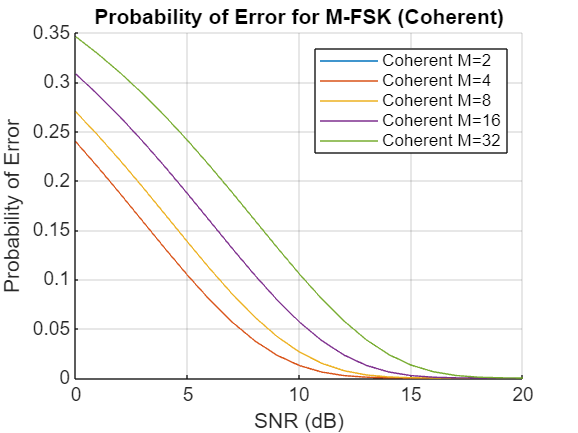


% MATLAB code for plotting probability of error for M-FSK (coherent and non-coherent)

% Clear all variables and close all figures
clear all;  clc;

% Define range of SNR (in dB)
SNR_dB = 0:1:20;
SNR_linear = 10.^(SNR_dB/10);

% Define different values of M (alphabet size)
M_values = [2, 4, 8, 16, 32];

% Initialize the probability of error matrices
Pe_coherent = zeros(length(M_values), length(SNR_dB));
Pe_noncoherent = zeros(length(M_values), length(SNR_dB));

% Calculate the probability of error for coherent and non-coherent M-FSK
for i = 1:length(M_values)
    M = M_values(i);
    for j = 1:length(SNR_dB)
        % Coherent M-FSK
        Pe_coherent(i, j) = 0.5 * erfc(sqrt(SNR_linear(j)/2) * sqrt(log2(M)/M));
       
        % Non-coherent M-FSK
        Pe_noncoherent(i, j) = 0.5 * exp(-SNR_linear(j)/(2 * (M - 1)));
    end
end

% Plotting the results
figure ;
hold on; grid on;
for i = 1:length(M_values)
    semilogy(SNR_dB, Pe_coherent(i, :), 'DisplayName', sprintf('Coherent M=%d', M_values(i)));    
end

% Add labels and title
xlabel('SNR (dB)');
ylabel('Probability of Error');
title('Probability of Error for M-FSK (Coherent)');
legend('show');
hold off;

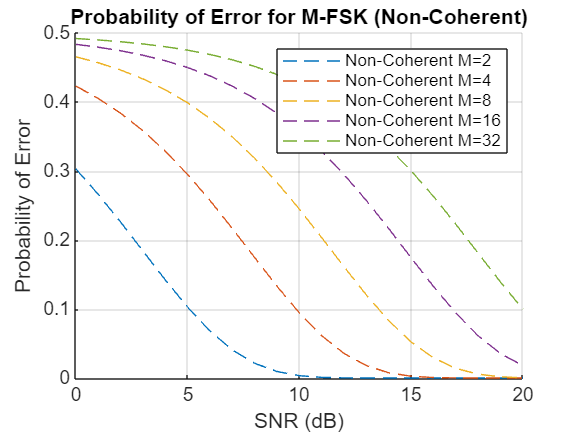


figure ;
hold on; grid on;
for i = 1:length(M_values)
    semilogy(SNR_dB, Pe_noncoherent(i, :), '--', 'DisplayName', sprintf('Non-Coherent M=%d', M_values(i)));  
end

% Add labels and title
xlabel('SNR (dB)');
ylabel('Probability of Error');
title('Probability of Error for M-FSK (Non-Coherent)');
legend('show');
hold off;

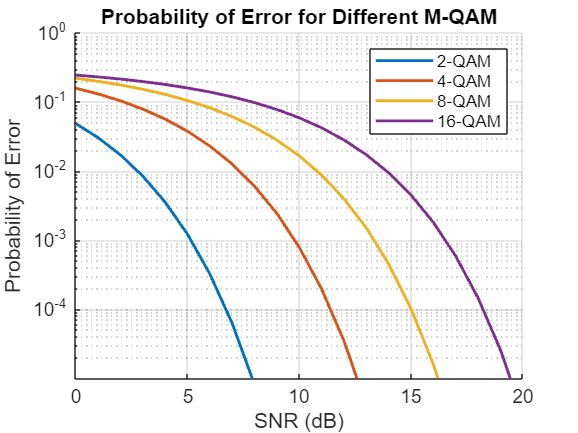


% MATLAB script to plot the probability of error for different values of M-QAM
clear;
clc;

% Define SNR range in dB
SNR_dB = 0:1:20;
SNR = 10.^(SNR_dB/10); % Convert SNR from dB to linear scale

% Define M values for M-QAM
M_values = [2,4,8,16];

% Probability of error calculation for M-QAM
Pe_MQAM = @(M, SNR) (2*(1-1/sqrt(M)).*erfc(sqrt(3*SNR/(2*(M-1))))/log2(M));

% Plot probability of error for different M-QAM
figure;
hold on;
for i = 1:length(M_values)
    M = M_values(i);
    Pe = Pe_MQAM(M, SNR);
    semilogy(SNR_dB, Pe, 'DisplayName', sprintf('%d-QAM', M), 'LineWidth', 1.5);
end

% Customize plot
grid on;
xlabel('SNR (dB)');
ylabel('Probability of Error');
title('Probability of Error for Different M-QAM');
legend('show');
set(gca, 'YScale', 'log'); % Set y-axis to logarithmic scale
xlim([0 20]);
ylim([1e-5 1]);

% Show the plot
hold off;

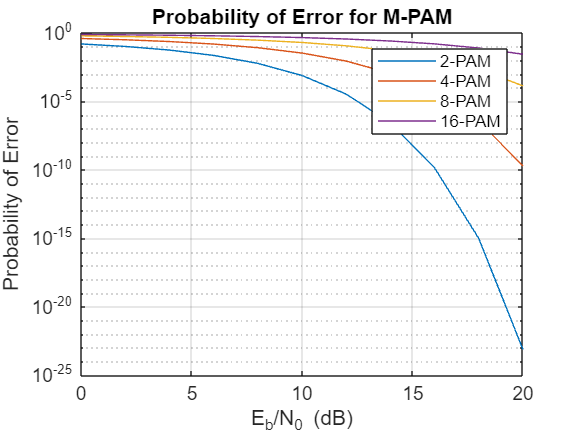


% MATLAB script to plot the probability of error for different values of M-PAM

% Define the values of M for M-PAM
M_values = [2, 4, 8, 16]; % Example values for M

% Define the range of Eb/N0 values (in dB)
EbN0_dB = 0:2:20;
EbN0 = 10.^(EbN0_dB/10); % Convert from dB to linear scale

% Pre-allocate the probability of error matrix
Pe = zeros(length(M_values), length(EbN0));

% Calculate the probability of error for each M
for i = 1:length(M_values)
    M = M_values(i);
    % Calculate the probability of error for M-PAM
    Pe(i, :) = 2 * (1 - 1/M) * qfunc(sqrt(3*log2(M)/(M^2-1) * EbN0));
end

% Plot the probability of error for each M
figure;
for i = 1:length(M_values)
    semilogy(EbN0_dB, Pe(i, :), 'DisplayName', sprintf('%d-PAM', M_values(i)));
    hold on;
end

% Set plot properties
grid on;
xlabel('E_b/N_0 (dB)');
ylabel('Probability of Error');
title('Probability of Error for M-PAM');
legend('show');